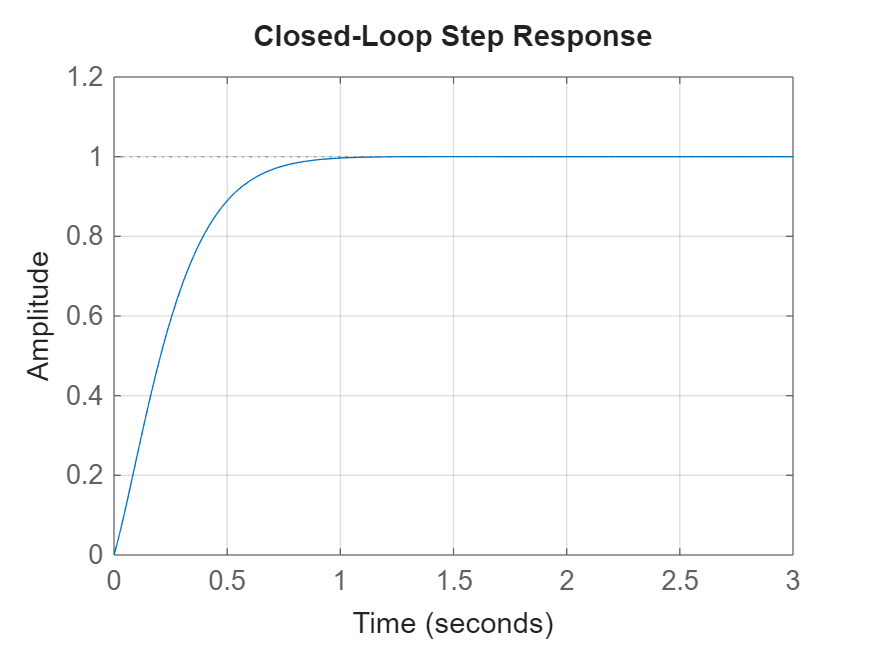

% DC motor plant
K = 1;
tau = 0.1;
G = tf(K, [tau 1 0]);   % K / (s*(tau*s + 1))

% Tuned PD controller
Kp = 4;
Kd = 0.2;
C = Kp + Kd*tf([1 0],1);

% Open-loop
L = C*G;

% Closed-loop
T = feedback(L,1);
% Plots
figure; step(T,3); grid on
title('Closed-Loop Step Response')

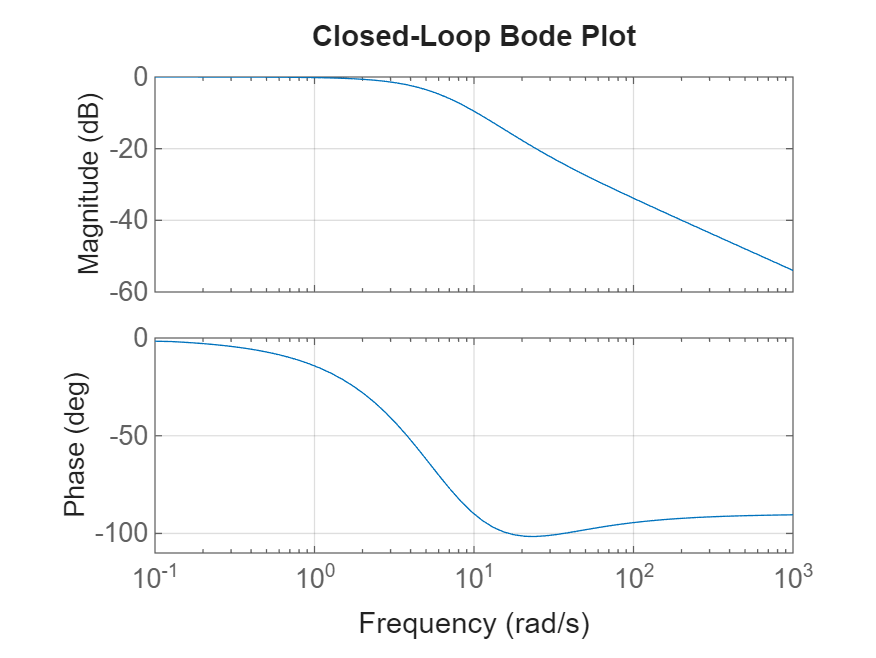


figure; bode(T); grid on
title('Closed-Loop Bode Plot')